HDPath = '/Volumes/JulieE8T/LMCResults/';
load(fullfile(HDPath,'MotorCoherence_amp_Operant_Trill.mat'))

FDR correction on the p-values

% Now correct that probability for False discovery rate (True proba =
% p*(Num_comparisons-rank))
[~,Ord]=sort(Info_pRandVoc);
Ord(Ord==length(Ord)) = length(Ord)-1;
Info_pRandVoc_FDR = Info_pRandVoc.*(length(Info_pRandVoc)-Ord);

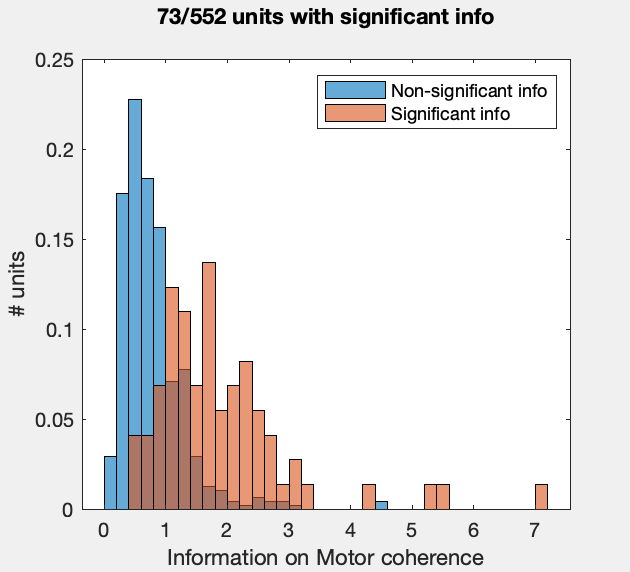

F1 = figure(1);
clf(F1)
set(F1,'Visible','on')
histogram(Info(Info_pRandVoc_FDR>=0.05),'BinWidth',0.2, 'Normalization','probability')
hold on
histogram(Info(Info_pRandVoc_FDR<0.05),'BinWidth',0.2, 'Normalization','probability')
legend('Non-significant info', 'Significant info')
hold off
ylabel('# units')
xlabel('Information on Motor coherence')
title(sprintf('%d/%d units with significant info\n',sum(Info_pRandVoc_FDR<0.05), sum(~isnan(Info))))

fprintf(1,'There are %d/%d cells with significant info\n',sum(Info_pRandVoc_FDR<0.05), sum(~isnan(Info)))

There are 73/552 cells with significant info


fprintf(1, 'Average Info for these cells is %.2f bits/s', mean(Info(Info_pRandVoc_FDR<0.05)))

Average Info for these cells is 1.88 bits/s

CellsPath(Info_pRandVoc_FDR<0.05).name

ans = '59834_20190612_SSS_1-81.mat'

ans = '59834_20190612_SSS_3-157.mat'

ans = '59834_20190612_SSS_3-191.mat'

ans = '59834_20190612_SSS_3-193.mat'

ans = '59834_20190614_SSS_1-100.mat'

ans = '59834_20190616_SSS_1-73.mat'

ans = '59834_20190616_SSS_1-77.mat'

ans = '59834_20190618_SSS_1-77.mat'

ans = '59834_20190619_SSM_1-86.mat'

ans = '59834_20190619_SSS_1-78.mat'

ans = '59834_20190619_SSS_4-208.mat'

ans = '59834_20190620_SSM_1-77.mat'

ans = '59834_20190621_SSM_1-84.mat'

ans = '59834_20190621_SSM_1-92.mat'

ans = '59834_20190621_SSS_1-76.mat'

ans = '59834_20190622_SSM_1-202.mat'

ans = '59834_20190622_SSS_1-84.mat'

ans = '59834_20190623_SSS_1-80.mat'

ans = '59834_20190624_SSM_1-233.mat'

ans = '59834_20190624_SSS_1-73.mat'

ans = '59834_20190625_SSM_1-253.mat'

ans = '59834_20190625_SSS_1-93.mat'

ans = '59834_20190626_SSM_1-232.mat'

ans = '59834_20190626_SSM_1-233.mat'

ans = '59834_20190626_SSS_1-87.mat'

ans = '59834_20190627_SSM_1-327.mat'

ans = '59834_20190627_SSM_1-329.mat'

ans = '59834_20190627_SSS_1-72.mat'

ans = '59834_20190627_SSS_4-318.mat'

ans = '59834_20190628_SSM_4-204.mat'

ans = '59834_20190628_SSS_1-98.mat'

ans = '59834_20190629_SSM_1-105.mat'

ans = '59834_20190629_SSM_1-271.mat'

ans = '59834_20190629_SSS_1-79.mat'

ans = '59834_20190629_SSS_3-213.mat'

ans = '59834_20190630_SSM_1-218.mat'

ans = '59834_20190630_SSM_1-219.mat'

ans = '59834_20190630_SSS_1-72.mat'

ans = '59834_20190630_SSS_3-184.mat'

ans = '59834_20190630_SSS_4-202.mat'

ans = '59834_20190701_SSM_1-103.mat'

ans = '59834_20190701_SSM_1-287.mat'

ans = '59834_20190702_SSM_1-67.mat'

ans = '59834_20190702_SSS_2-85.mat'

ans = '59834_20190704_SSM_1-84.mat'

ans = '59834_20190704_SSS_2-130.mat'

ans = '59834_20190705_SSM_1-266.mat'

ans = '59834_20190705_SSM_4-268.mat'

ans = '59834_20190705_SSS_2-114.mat'

ans = '59834_20190706_SSM_1-303.mat'

ans = '59834_20190708_SSM_1-228.mat'

ans = '59834_20190710_SSM_1-196.mat'

ans = '59834_20190711_SSM_1-262.mat'

ans = '59834_20190711_SSM_1-98.mat'

ans = '59834_20190711_SSM_4-271.mat'

ans = '11689_20190118_SSM_1-81.mat'

ans = '11689_20190129_SSM_3-163.mat'

ans = '11689_20190129_SSS_1-77.mat'

ans = '11689_20190130_SSS_1-250.mat'

ans = '11689_20190130_SSS_3-260.mat'

ans = '11689_20190131_SSM_1-227.mat'

ans = '11689_20190131_SSM_3-232.mat'

ans = '11689_20190131_SSS_1-137.mat'

ans = '11689_20190201_SSM_1-70.mat'

ans = '11689_20190201_SSM_1-76.mat'

ans = '11689_20190201_SSS_1-90.mat'

ans = '11689_20190202_SSM_1-167.mat'

ans = '11689_20190202_SSM_3-147.mat'

ans = '11689_20190202_SSS_1-172.mat'

ans = '11689_20190204_SSM_3-195.mat'

ans = '11689_20190212_SSM_1-168.mat'

ans = '11689_20190212_SSM_2-131.mat'

ans = '11689_20190212_SSM_4-157.mat'

save(fullfile(HDPath,'MotorCoherence_amp_Operant_Trill.mat'), 'Info_pRandVoc_FDR', '-append')